# [Split Data: Train, Validate, Test](https://apmonitor.com/pds/index.php/Main/SplitData)

Splitting data ensures that there are independent sets for training, testing, and validation. Data can be divided into sequential blocks where the order is preserved (e.g. time series) or with random selection (shuffle). Cross-validation demonstrates the effect of choosing alternating test sets.

The test set is to evaluate the model fit independently of the training and to improve the hyper-parameters without overfitting on the training. Scikit-learn has a train / test split function with a *test_size* that is the fraction to reserve for testing.

## **One Input, Two Outputs**

When the data is combined into one set, there are two outputs as train and test sets. The input must be an array.

In this case, 20% of the data at the end is saved for testing. Shuffling the data is not needed because the data sequence is important as a time series.

data = readtable('http://apmonitor.com/pds/uploads/Main/tclab_data6.txt')

data = 3601×5 table
    Time    Q1    Q2     T1       T2  
    ____    __    __    _____    _____

      0     0     0     16.06       16
      1     0     0     16.06    15.97
      2     0     0     16.06    16.03
      3     0     0     16.03       16
      4     0     0     16.03    15.94
      5     0     0     16.06       16
      6     0     0     16.03       16
      7     0     0     16.06    15.94
      8     0     0     16.06    15.97
      9     0     0     16.06    15.97
     10     0     0     16.06    15.94
     11     0     0     16.06    15.97
     12     0     0     16.06    15.97
     13     0     0     16.06    15.94
     14     0     0     16.06    15.94
     15     0     0     16.06    15.94


data.Time = [];
d_array = table2array(data)

d_array =          0         0   16.0600   16.0000
         0         0   16.0600   15.9700
         0         0   16.0600   16.0300
         0         0   16.0300   16.0000
         0         0   16.0300   15.9400
         0         0   16.0600   16.0000
         0         0   16.0300   16.0000
         0         0   16.0600   15.9400
         0         0   16.0600   15.9700
         0         0   16.0600   15.9700



% Split into train and test subsets (20% for test)
train_idx = floor(0.8 * height(data));
train_data = data(1:train_idx,:);
test_data = data(train_idx+1:end,:);

fprintf('Train: %d\n', height(train_data))

Train: 2880


disp(head(train_data))

    Q1    Q2     T1       T2  
    __    __    _____    _____

    0     0     16.06       16
    0     0     16.06    15.97
    0     0     16.06    16.03
    0     0     16.03       16
    0     0     16.03    15.94
    0     0     16.06       16
    0     0     16.03       16
    0     0     16.06    15.94



fprintf('Test: %d\n', height(test_data))

Test: 721


disp(head(test_data))

    Q1    Q2     T1       T2  
    __    __    _____    _____

    0     0     59.25    27.02
    0     0     59.22    27.02
    0     0     58.99    27.02
    0     0     58.93    27.02
    0     0     58.93    27.02
    0     0     58.64    27.02
    0     0      58.6    27.02
    0     0      58.6    27.02



## **Two Inputs, Four Outputs**

When the data is already split into features and labels, there are two inputs to the function. The four outputs are X_train, X_test, y_train, and y_test. The inputs must be an array. You can generate a sample data set for this with the make_classification function from MATLAB's file exchange: [https://www.mathworks.com/matlabcentral/fileexchange/108869-make_classification](https://www.mathworks.com/matlabcentral/fileexchange/108869-make_classification) (Author: Jian Wang). Download the function and place the Simulate_Data_Classification.m file in the same folder as this MATLAB file and the function should work as follows.

% Generate random dataset
n_samples = 5000;
n_features = 20;
n_informative = 15;

[X, y] = Simulate_Data_Classification('nsamples', 5000, 'nfeatures', 20, 'ninformative', 15);

% Split into training and testing data
test_size = 0.2;
idx = randsample(n_samples, round(n_samples * test_size));
X_test = X(idx, :);
y_test = y(idx, :);
X_train = X;
X_train(idx, :) = [];
y_train = y;
y_train(idx, :) = [];


fprintf('Number of samples: %d\nNumber of training samples: %d\nNumber of testing samples: %d\n', length(X), length(X_train), length(X_test))

Number of samples: 5000
Number of training samples: 4000
Number of testing samples: 1000


## **Train, Validation, Test**

The validation may come with a third split to evaluate the hyperparameter optimization. Validation data is a split of the training set to use during the fitting. It is training data that is reserved for evaluating the loss function to detect overfitting.

**Cross-Validation**

Cross-validation is an alternative approach to divide the training data into multiple sets that are fit separately and tested on the other set.

The parameter consistency is compared between the multiple models. This example shows how to perform a cvpartition cross-validation with the data split 5 ways.

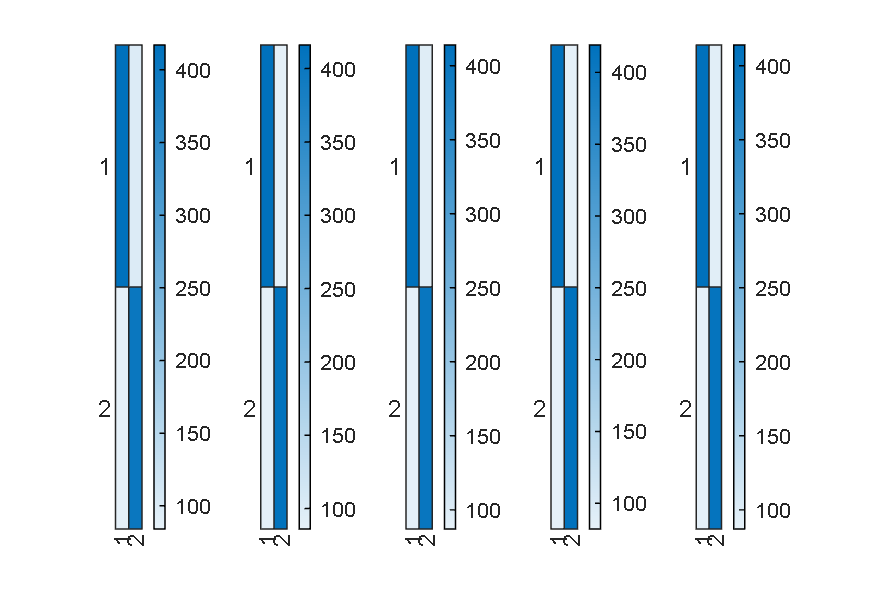

% define dataset
[Xcv, ycv] = Simulate_Data_Classification('nsamples', 5000, 'nfeatures', 20, 'ninformative', 15);

% Set up cvpartition cross validation
cv = cvpartition(ycv, 'KFold', 5);

% Initialize model
dtc = fitctree(Xcv,ycv);

% Array to store accuracy scores
scores = zeros(5, 1);

% Initialize plot
figure('units','normalized','outerposition',[0 0 1 1])

for i=1:5
    train_index_cv = training(cv, i);
    test_index_cv = test(cv, i);
    
    Xtrain_cv = Xcv(train_index_cv, :);
    Xtest_cv = Xcv(test_index_cv, :);
    ytrain_cv = ycv(train_index_cv, :);
    ytest_cv = ycv(test_index_cv, :);

    dtc_cv = fitctree(Xtrain_cv, ytrain_cv);
    yp_cv = predict(dtc_cv, Xtest_cv);
    acc = mean(yp_cv == ytest_cv);
    scores(i) = acc;

    subplot(1,5,i)
    cm = confusionmat(yp_cv, ytest_cv);
    heatmap(cm)
    
end


disp(['Accuracy: ', num2str(mean(scores) * 100), '%']);

Accuracy: 82.32%


A confusion matrix is a graphical representation of misclassification errors. The accuracy of the classifier over the 5 cases is 82%.